## Gravitational wave data: first look

We will take a look at a short segment of data from the LIGO Hanford detector. This is the data segment, from LIGO-Hanford, that contains the first detected GW signal, GW150914.

The data file can be obtained from the Gravitational Wave Open Science Center (GWOSC). Data files are provided in the widely used [HDF5 format](https://portal.hdfgroup.org/display/HDF5/Introduction+to+HDF5). See the image below for how to access data file used here.

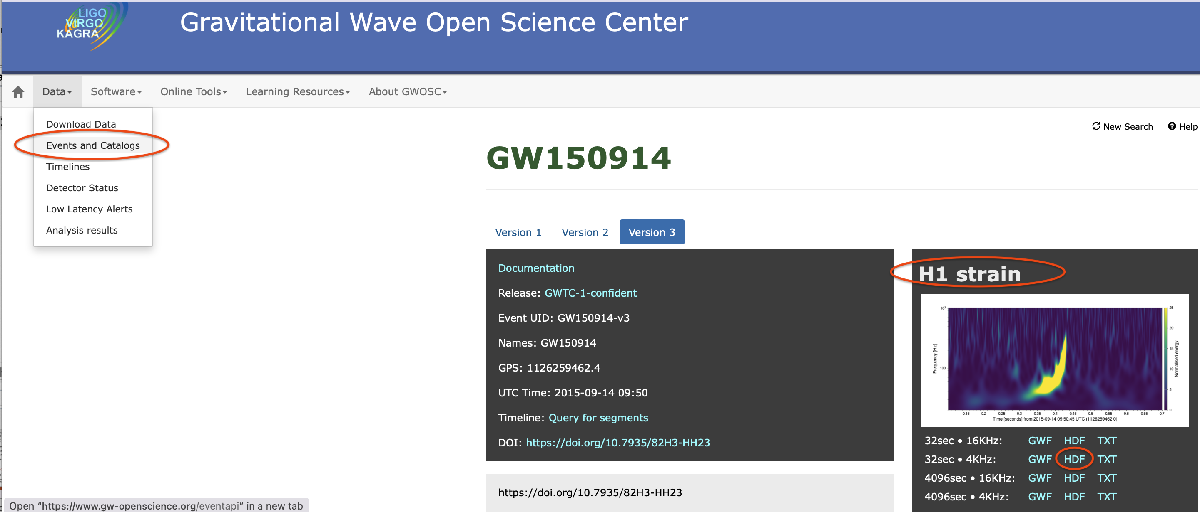

A single HDF5 file can store multiple types of data as well as information, called attributes, for each type of data. The contents of an HDF5 are organized in a way that is quite similar to a hierarchy of directories and files on a computer. First let us look at the contents of the GW data file.

ls; %List the files in this folder

H-H1_GWOSC_4KHZ_R1-1126259447-32.hdf5	sigprocgwdat.mlx
readgwoscdat.mlx			whitening.mlx



You see that an HDF5 file is identified by the extension **.hdf5**.

The file name conveys some basic information about the data including the detector (H1 or LIGO, Hanford), the sampling frequency (4kHz), the start GPS time (1126259447), and the duration (32 sec). Note that all this information is stored within the file itself, so one also save the data under a more convenient file name that's easier to remember.

We can read the GW strain data stored in the file using the following steps.

dataVec = h5read('H-H1_GWOSC_4KHZ_R1-1126259447-32.hdf5','/strain/Strain');

The sampling frequency (in Hz) can be obtained using this set of commands.

%Sampling interval
samplIntrvl = h5readatt('H-H1_GWOSC_4KHZ_R1-1126259447-32.hdf5','/strain/Strain','Xspacing');
%Sampling frequency
samplFreq = 1/samplIntrvl;
disp(samplFreq);

        4096



We can construct a vector of time samples,

nSamples = length(dataVec);
timeVec = (0:(nSamples-1))*samplIntrvl;

and plot the data.

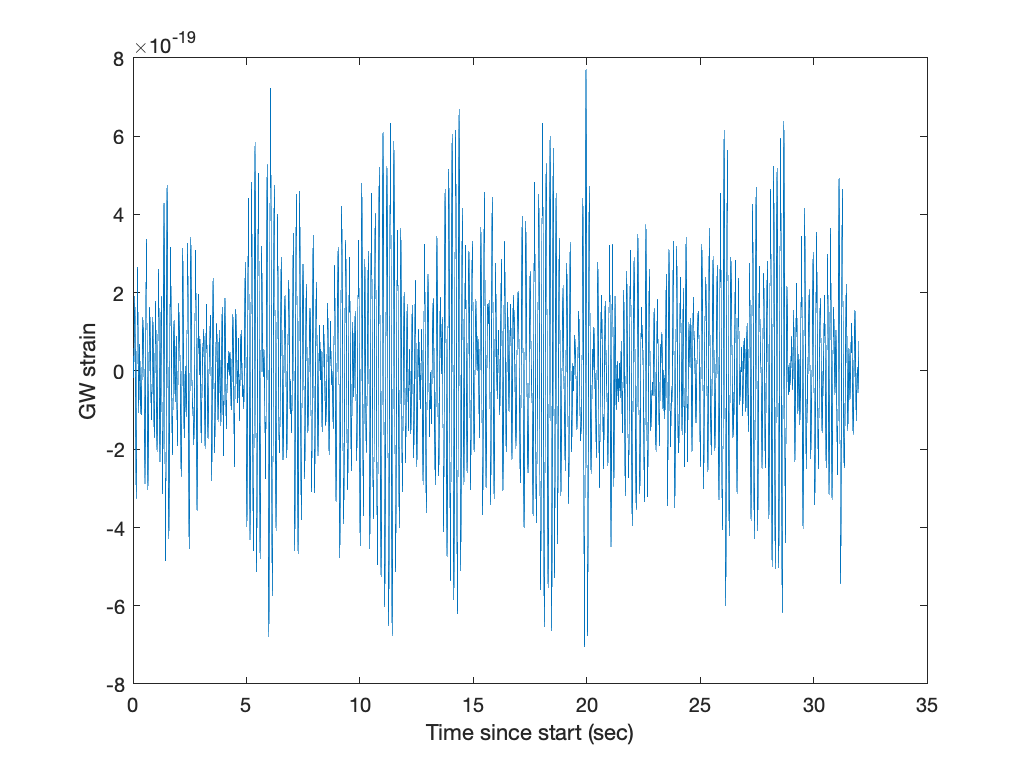

tdFig=figure;
plot(timeVec,dataVec);
xlabel('Time since start (sec)');
ylabel('GW strain');

## Spectral analysis

Compute the FFT of the data.

dataFFT = fft(dataVec);

Compute the positive DFT frequencies. These range from 0 Hz to half the sampling frequency (Nyquist theorem).

%Index of highest positive frequency
kNyq = floor(nSamples/2)+1; 
%Positive DFT frequencies from 0 to highest positive frequency
posFreq = (1:kNyq)/(nSamples/samplFreq); 

Plot the absolute value of the data FFT .

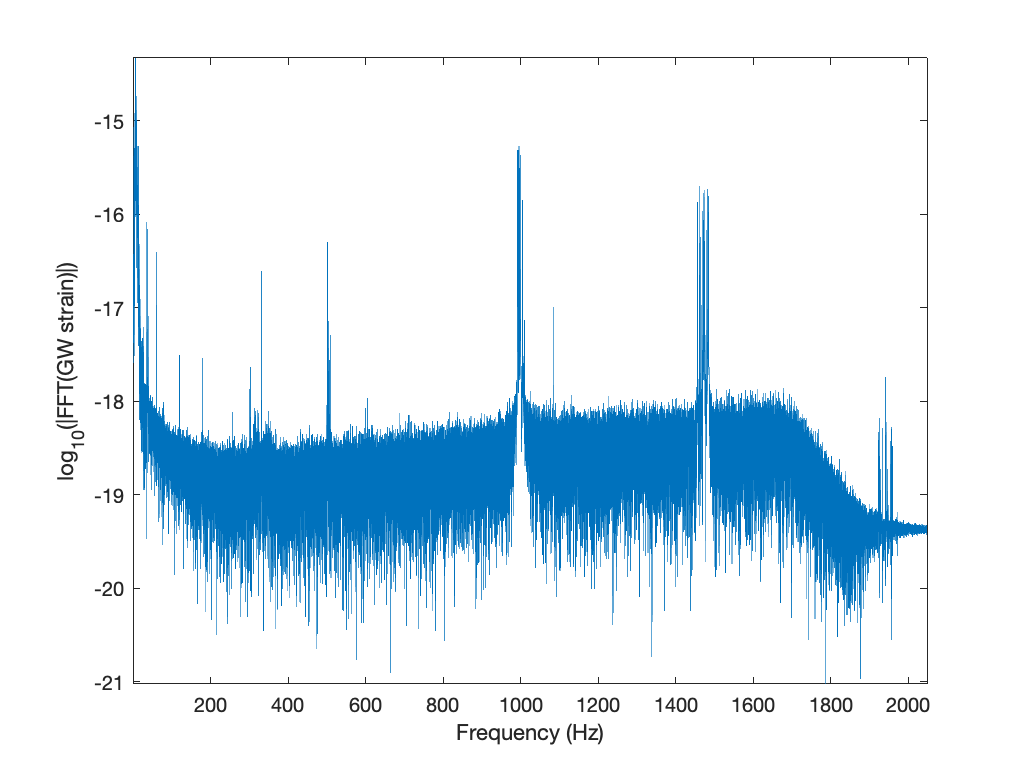

figure;
plot(posFreq, log10(abs(dataFFT(1:kNyq))));
axis tight;
xlabel('Frequency (Hz)');
ylabel('log_{10}(|FFT(GW strain)|)')

We see that there is a large variation in the magnitude of the spectrum as a function of frequency. This is typically a situation where one should use **windowing** in order to reduce spectral leakage.

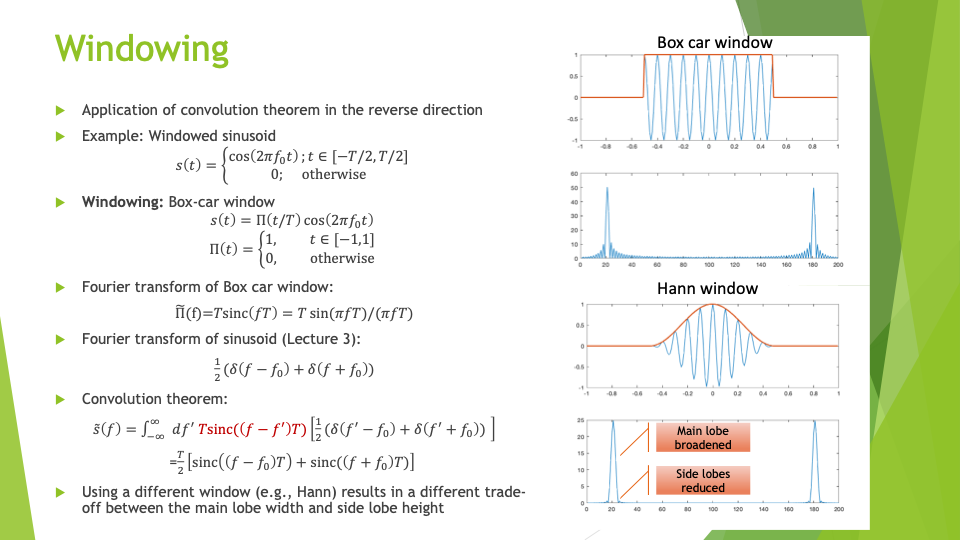

Let us apply a Hann window and plot the spectrum again.

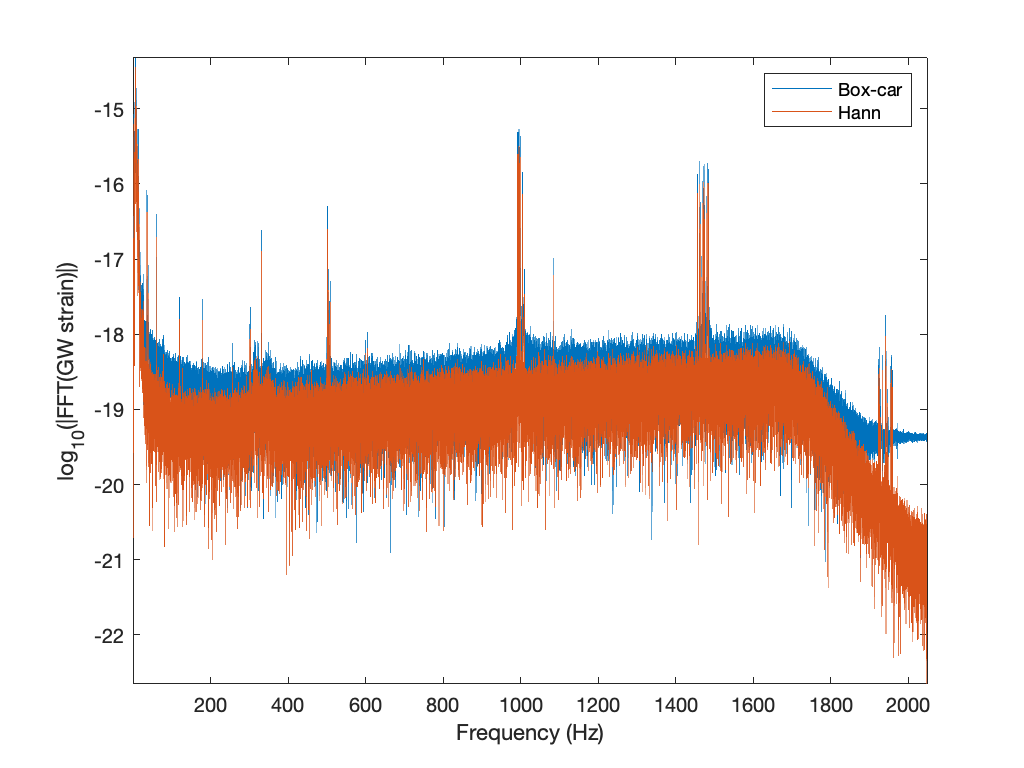

pdFig = figure;
winDataFFT = fft(hann(nSamples).*dataVec);
plot(posFreq, log10(abs(dataFFT(1:kNyq))));
hold on;
plot(posFreq, log10(abs(winDataFFT(1:kNyq))));
axis tight;
xlabel('Frequency (Hz)');
ylabel('log_{10}(|FFT(GW strain)|)')
legend('Box-car','Hann');

You can zoom into one of the high-power narrowband features (called "lines") and see the difference different windows make. Spectral leakage from the large power at low frequencies can affect the spectrum over a broad range if not a proper window is not used.